# Some examples for the application of remezex()

Execution date

datetime("today")

ans = datetime
   01-Jan-2024


## Example 1: exp()

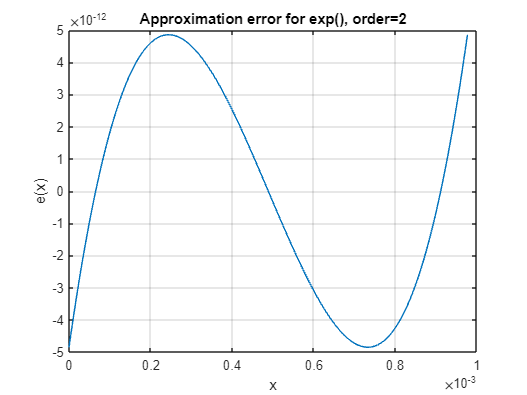

fun_str  = "exp()";
fun      = @(x) exp(x);
fun_der  = @(x) exp(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true);
plot_demo(fun, fun_str, p, interval);

## Example 2: exp()

interval = [-8 0];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true, 'verbosity', 2);

*** Start of iteration 1 ***
Polynomial coefficients: 
0.000311073, 0.00785386, 0.0773207, 0.37625, 0.933457, 0.994317
Error: 0.0056832
Error function root #1 in interval [-8, -7.4181]: -7.8447
Error function root #2 in interval [-7.4181, -5.9193]: -6.6882
Error function root #3 in interval [-5.9193, -4.0053]: -4.7758
Error function root #4 in interval [-4.0053, -2.0188]: -2.6521
Error function root #5 in interval [-2.0188, -0.5416]: -0.96429
Error function root #6 in interval [-0.5416, 0]: -0.1041
Extremum #1 in interval [-8, -7.8447] at -8 with error 0.0056832
Extremum #2 in interval [-7.8447, -6.6882] at -7.3926 with error 0.0056967
Extremum #3 in interval [-6.6882, -4.7758] at -5.7823 with error 0.0058274
Extremum #4 in interval [-4.7758, -2.6521] at -3.6813 with error 0.0063776
Extremum #5 in interval [-2.6521, -0.96429] at -1.7237 with error 0.0065833
Extremum #6 in interval [-0.96429, -0.1041] at -0.43227 with error 0.0061065
Extremum #7 in interval [-0.1041, 0] at 0 with error 

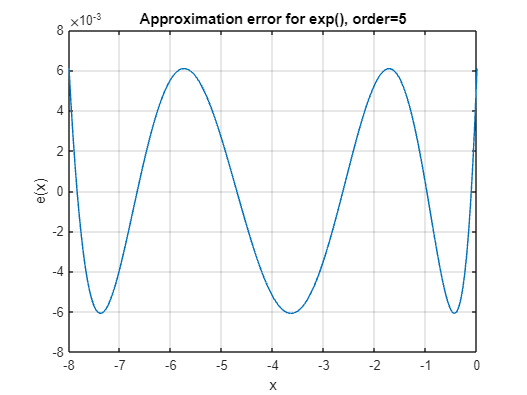

plot_demo(fun, fun_str, p, interval);

## Example 3: sin()

fun_str  = "sin()";
fun      = @(x) sin(x);
fun_der  = @(x) cos(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 1);

*** Start of iteration 1 ***
Shifting x(2)=0.00023469 by 9.4866e-06
*** Start of iteration 2 ***
Shifting x(3)=0.00073284 by -4.1553e-07
*** Start of iteration 3 ***
Shifting x(2)=0.00024417 by -3.1016e-08
*** Start of iteration 4 ***
Best approximation polynomial of order 2 over [0, 0.00097656] with max abs error 4.8506e-12:
-2.441406094249032e-04 * x^2
+1.000000089406958e+00 * x^1
-4.850637787058939e-12


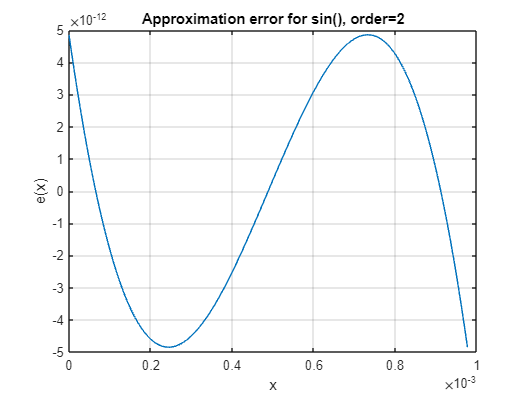

plot_demo(fun, fun_str, p, interval);

## Example 4: sin()

interval = [-8 0];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 1);

*** Start of iteration 1 ***
Shifting x(4)=-3.8821 by -0.41569
*** Start of iteration 2 ***
Shifting x(5)=-1.9577 by -0.39384
*** Start of iteration 3 ***
Shifting x(6)=-0.54891 by -0.16164
*** Start of iteration 4 ***
Shifting x(3)=-5.907 by -0.20851
*** Start of iteration 5 ***
Shifting x(2)=-7.4629 by -0.020804
*** Start of iteration 6 ***
Shifting x(4)=-4.2978 by 0.01816
*** Start of iteration 7 ***
Shifting x(5)=-2.3516 by 0.0081268
*** Start of iteration 8 ***
Shifting x(6)=-0.71055 by 0.0021313
*** Start of iteration 9 ***
Shifting x(3)=-6.1155 by -0.0014392
*** Start of iteration 10 ***
Shifting x(2)=-7.4838 by -6.8678e-05
*** Start of iteration 11 ***
Shifting x(4)=-4.2796 by 1.9589e-05
*** Start of iteration 12 ***
Shifting x(5)=-2.3435 by 3.1563e-06
*** Start of iteration 13 ***
Shifting x(6)=-0.70842 by 4.2602e-07
*** Start of iteration 14 ***
Best approximation polynomial of order 5 over [-8, 0] with max abs error 0.079434:
-2.451165635256927e-03 * x^5
-3.541362747995714e-

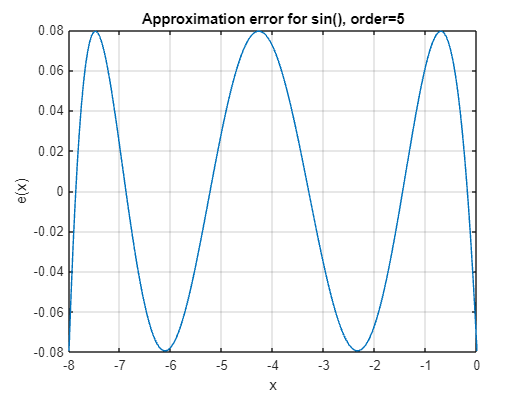

plot_demo(fun, fun_str, p, interval);

## Example 5: atan()

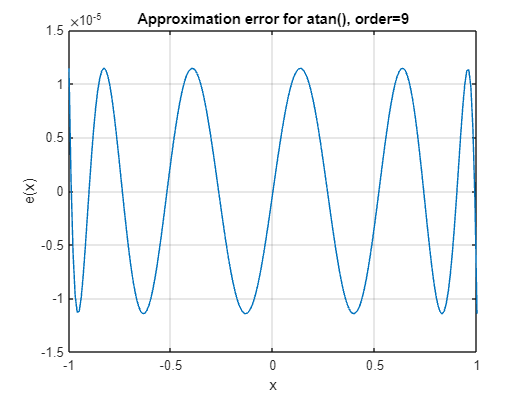

fun_str  = "atan()";
fun      = @(x) atan(x);
fun_der  = @(x) 1./(x.^2+1);
interval = [-1 1];
order    = 9;
[p, ~] = remezex(fun, fun_der, interval, order);
plot_demo(fun, fun_str, p, interval);

## Helper function

function plot_demo(fun, fun_str, p, interval)
    % plotting the error of the whole interval
    numTestPoints = 200;
    x = linspace(interval(1), interval(2), numTestPoints);
    e = fun(x) - polyval(p, x);
    figure();
    plot(x, e);
    xlabel('x'); ylabel('e(x)'); grid on;
    order = numel(p)-1;
    title("Approximation error for " + fun_str + ", order=" + order);
end